% データリスト読み込み
list = dir('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0620/*.csv');
% dataの階層
pl = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0620/';

x=linspace(0,2,1200000)

x =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


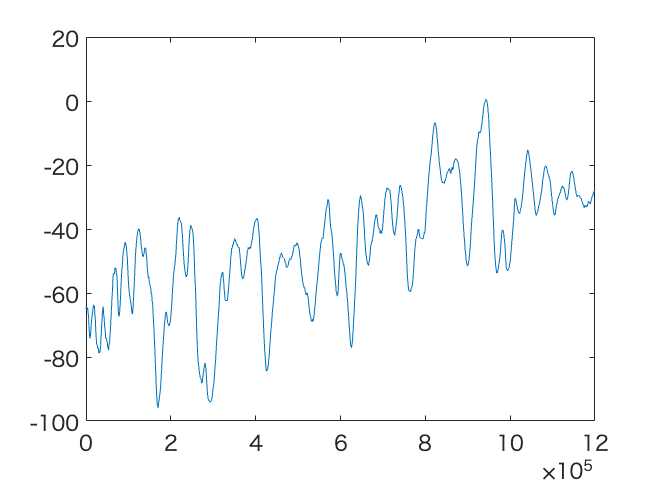

for n = 1 : length(list)
    % list(n,1)に書いてある名前のcsvファイルをreadmatrixで読み込み
    data = readmatrix( [pl list(n).name] );
    Num = extractBefore( list(n).name, '.csv' );
    y = data( 1:end, 3 ); % 計測data
    
    plot(y)
    ax = gcf;

    filename = append(pl, 'figure/' , Num , '.eps');
    exportgraphics(ax, filename, 'Resolution', 300);
end